# Voltmeter Loading Errors

30 Jan 25 B.R

## Objective

A good question is why $R_{Thevenin}$ was ignored when we measure the open circuit voltage and equated to $V_{Thevenin} = V_{OC}$. I replied that an "ideal" voltmeter doesn't draw any current, so there is no voltage drop across $R_{Th}$ in that measurement. Let's empirically verify this, and also verify Kirchhoff's Voltage Law (KVL), that the sum of the voltages around any circuit is zero. 

## Methods

Connect the wall wart (12VDC, 1A) to two resistors of the same value in series, e.g., R1=R2=10k in Fig. 1. 

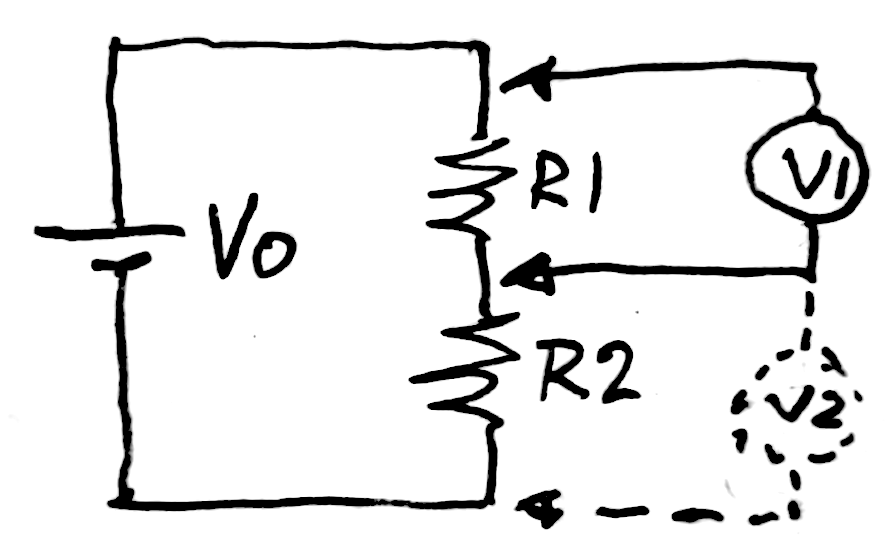

    Figure 1. Schematic to measure voltmeter loading.

Measure sequentially Vo (= $V_{OC} = V_{Thevenin}$ of the wall wart), V1, and V2 with the voltmeter (Neotech NT8233D Pro). Note that we're ignoring the wall wart's $R_{Thevenin} \leq 1\Omega$ (measured previously), which is justified when R1+R2 is much, much larger. 

## Results

1. R1 = R2 = 10k$\Omega$, V0 = 12.15V, V1 = 6.07V, V2 = 6.07V.

And the (signed) sum of the voltages around the loop = 0 to within measurement uncertainty.

2. R1 = R2 = 1M$\Omega$, V0 = 12.15V, V1 = 5.81V, V2 = 5.75V

Thus clearly, $\sum_{i=0}^2 V_i = 0$ = -12.15 + 5.81 + 5.75 ... oops??!!

## Discussion

The voltage divider equation tells us $V2 = V_0\frac{R2}{R1+R2} = V_0/2$, and the same for V1. In summing around the loop, the battery (source) has opposite sign as the resistors -- since current comes out of the + end of the battery but enters the + ends of the resistors (tops in Fig. 1) -- so the sum of the voltages is zero. But that didn't happen in the last data set! 

The percent error in the last data set might be characterized as 

(12.15 -5.81 - 5.75) / 12.15 * 100 % percent error

ans = 4.8560

 But it is also an absolute error of 

(12.15 -5.81 - 5.75) % volts

ans = 0.5900

and I'm not willing to forgive 0.6 volts to "noise" or "cheap voltmeter", etc. So let's try to model the error -- model the "cheap voltmeter" as a (Thevenin) resistor. Instead of an "ideal voltmeter" that draws no current, model it as (unknown) Rv in parallel with R1 or R2 when the measurement is taken. Focus on V2, we need to substitute for R2 in the voltage divider equation R2 || Rv ("R2 in parallel with Rv"), let's call that unknown Rp for now. The voltage divider equation tells us:


$$5.75V = 12.15V * \frac{Rp}{R1+Rp}$$


One equation with one unknown, straightforward enough to solve with some annoying algebra. Let me show you another way, for as the saying goes, "The carpenter with a hammer in their hand sees the world as nails." With Matlab, I'll guess the solution. The fraction is around 1/2, and R1 is 1e6 ohms, so Rp must also be around 1e6 ohms. 

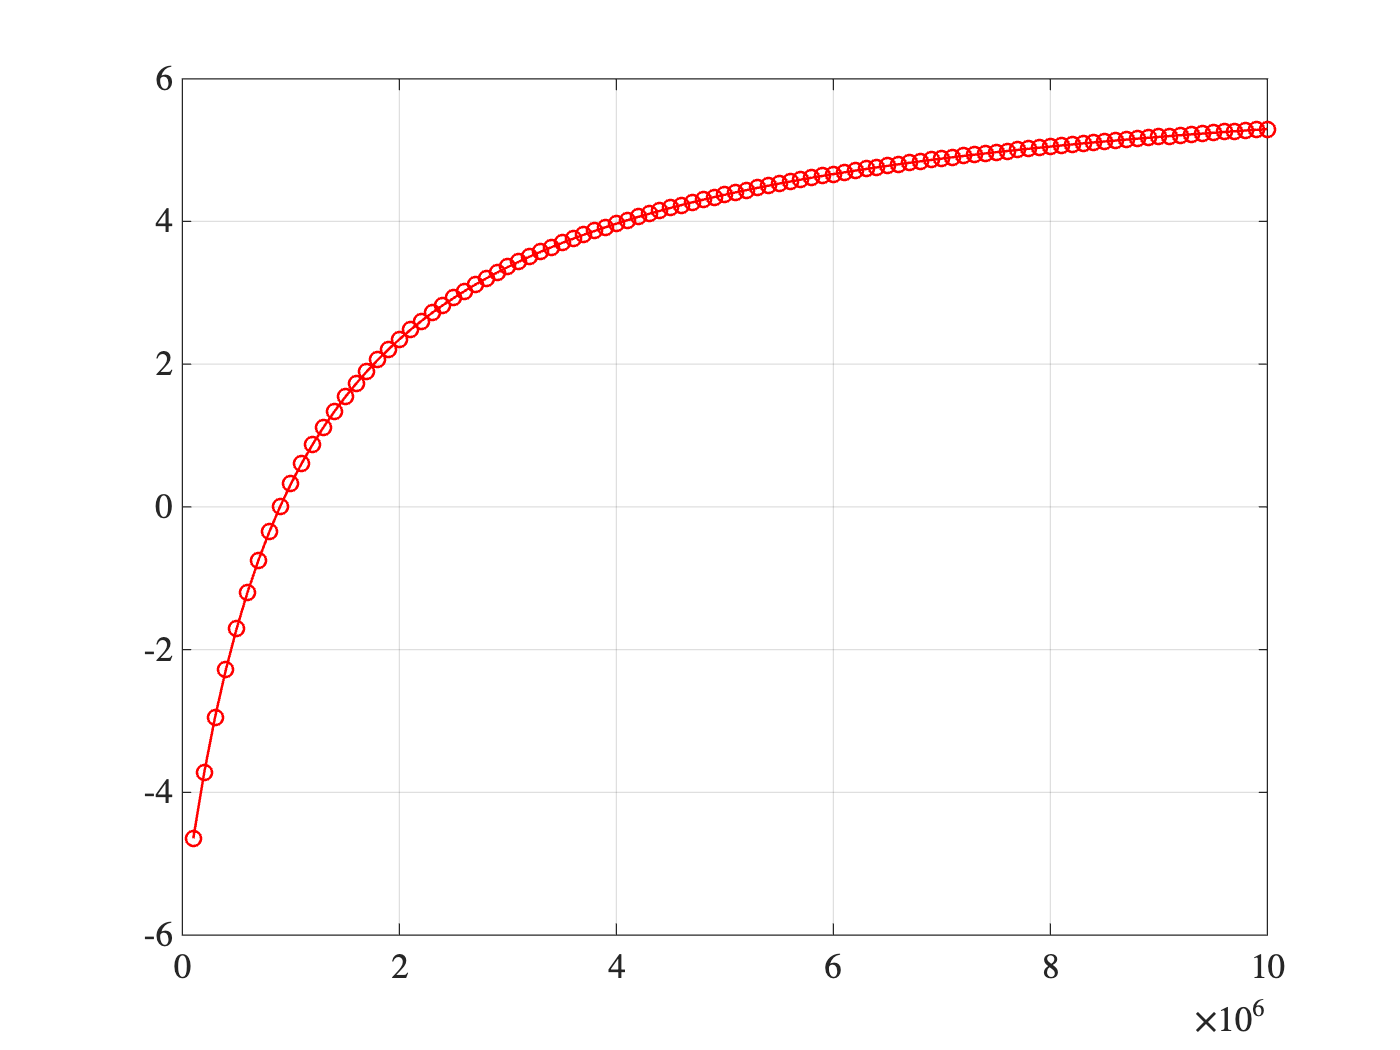

Rp = linspace(1e5,1e7)'; % a bunch of guesses
err = 12.15 * Rp ./ (1e6+Rp)-5.75; % error
plot(Rp, err, 'o-'); grid

    Figure 2. plot of error vs. guessed value of Rp = R2 || Rvoltmeter.

The solution is the value of Rp where the error, `err = 0`. The zero crossing is in the plot, so we could zoom in and read off the value of the nearest point. But we can do better using interpolation:

help spline

 spline - Cubic spline data interpolation
    This MATLAB function returns a vector of interpolated values s
    corresponding to the query points in xq.

    Syntax
      s = spline(x,y,xq)
      pp = spline(x,y)

    Input Arguments
      x - x-coordinates
        vector
      y - Function values at x-coordinates
        vector | matrix | array
      xq - Query points
        scalar | vector | matrix | array

    Output Arguments
      s - Interpolated values at query points
        scalar | vector | matrix | array
      <a href="m

Since we're looking for the x value corresponding to y = 0, we need to flip x and y:

spline(err, Rp, 0)

ans = 8.9844e+05

Verify this is consistent with the graph (the first time I did this, I forgot to flip x and y, and `spline(Rp, err, 0)` returned -5.75, obviously the wrong intercept). Always sanity-check computed results.

What does this *mean*? That the voltmeter "loaded" R2, reducing its *effective* value from 1000k$\Omega$ to 898k$\Omega$. 

What is Rv then, the impedance of the voltmeter? The equation for two parallel resistors is 

$Rp = \frac {R_AR_B}{R_A+R_B}$, so we can plug in numbers: $898k\Omega = 1M\Omega * Rv/(1M\Omega+Rv)$, another single equation with one unknown that can be solved with tedious algebra, or guess and interpolate a solution. The fraction is a little less than 1, suggesting Rv >1M. 

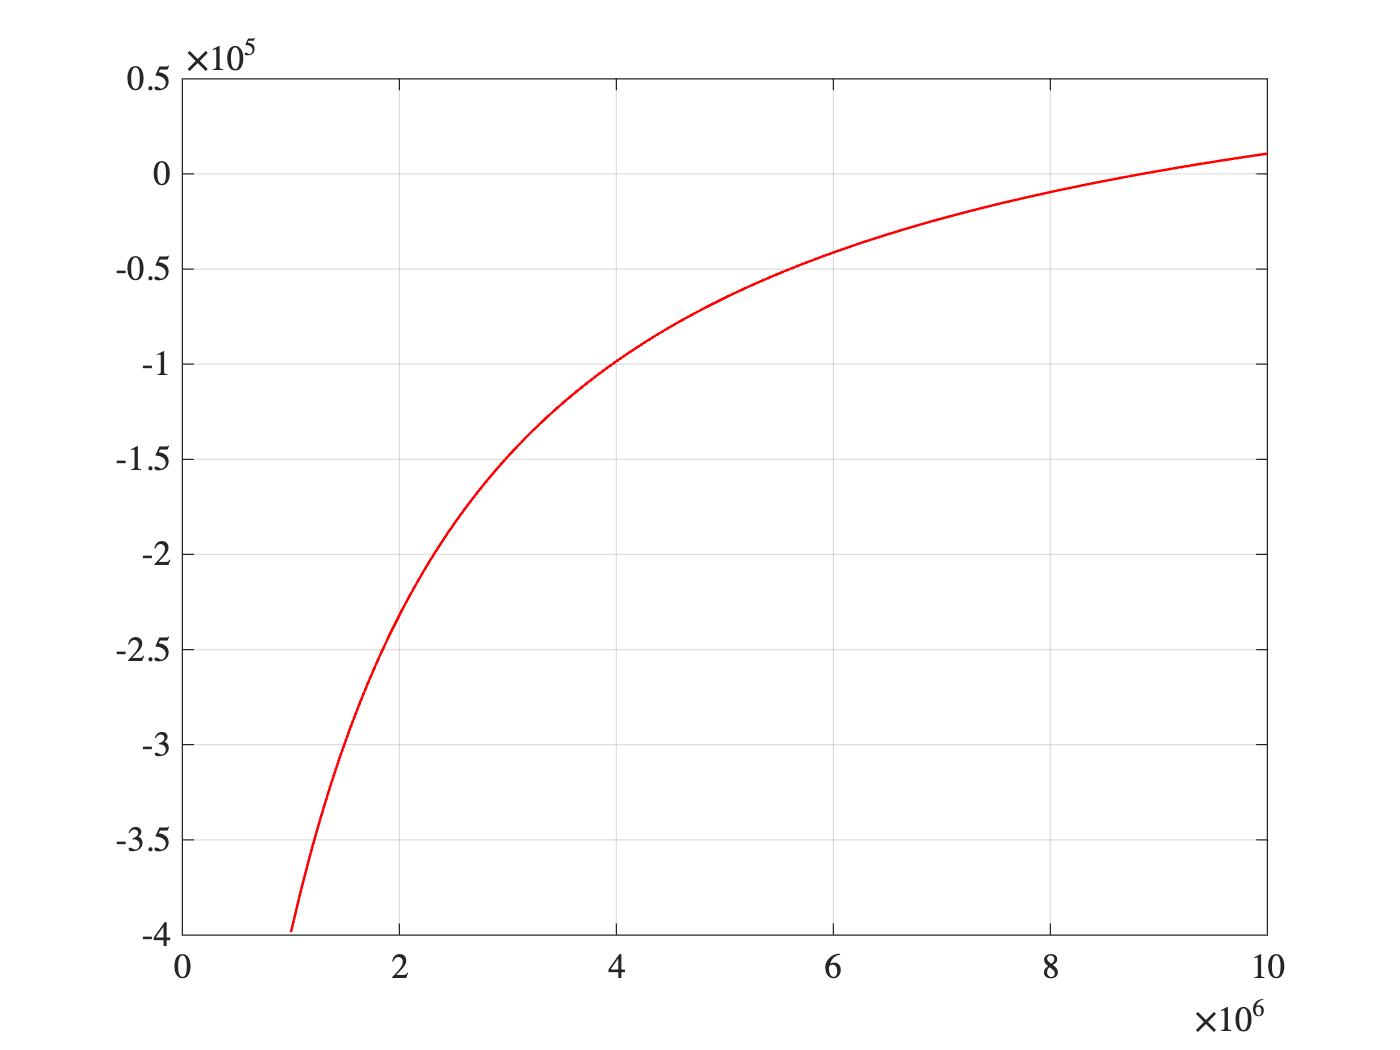

Rp = ans; % save the answer from spline above
Rv = linspace(1e6,10e6)';
err = 1e6 * Rv ./ (1e6 + Rv) - Rp;
plot(Rv, err); grid;

    Figure 3. plot of error vs. guessed value of Rvoltmeter.

The root (zero crossing) is again in the domain, so we can `spline` to find it:

spline(err, Rv, 0)

ans = 8.8462e+06

Our voltmeter is behaving like an 8.85M$\Omega$ resistor between its red and black probes. Let's just double check that we did this right by simulating the equivalent circuit:

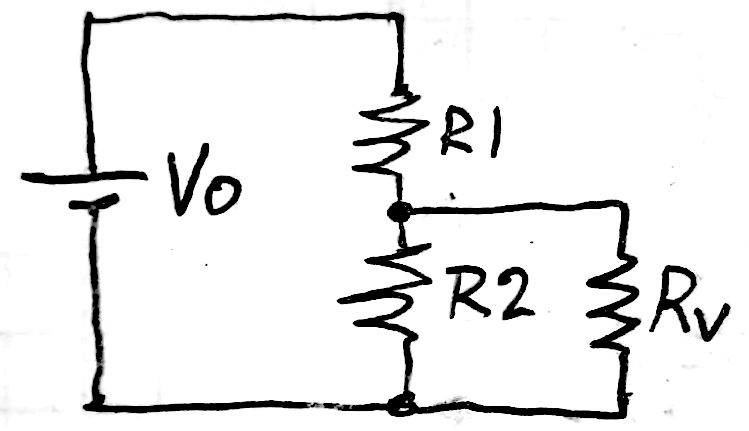

    Figure 4. Equivalent circuit of the (real) voltmeter measuring V2.

Vo = 12.15; % volts
R1 = 1e6; % ohms
R2 = R1;
Rv = ans; % from spline above
Rp = R2 * Rv / (R2 + Rv); % parallel resistor equation
V2 = Vo * Rp / (R1 + Rp) % voltage divider eqn, measured 5.75V

V2 = 5.7500

## Conclusions

The resistance (later we'll call it "impedance") of my voltmeter is around 8.8M$\Omega$, which loads or reduces the impedance of the device it is connected across. Across a 10k resistor, it reduces the resistor to: 

10e3 * Rv / (10e3+Rv)

ans = 9.9887e+03

a percent error of 

(10e3-ans)/10e3 * 100

ans = 0.1129

or a little more than "one part per thousand", which is why we didn't measure/notice it. But the loading error increases as the resistance (impedance) of the "source" of the measurement increases. Here's another way to quantify the loading error graphically: 

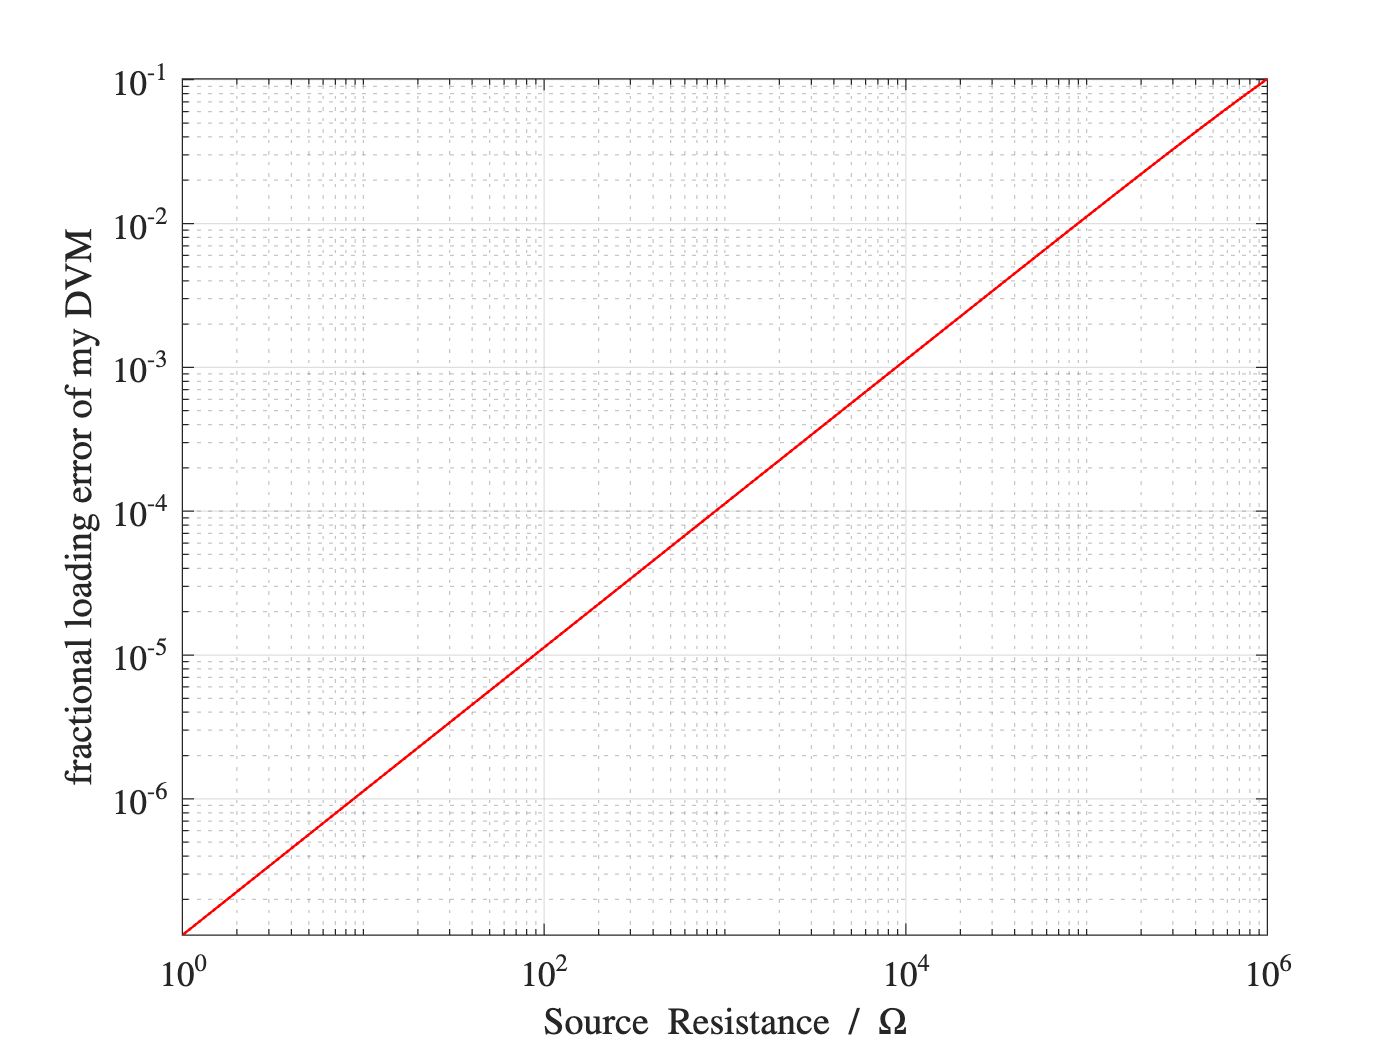

Rsource = logspace(0,6)';
Rp = Rsource * Rv ./ (Rsource + Rv);
err = (Rsource - Rp) ./ Rsource; 
loglog(Rsource, err); grid; axis tight
xlabel('Source Resistance / \Omega')
ylabel('fractional loading error of my DVM')

    Figure 5. Loading error vs. source resistance for my DVM.

Voltages across 100k resistors have 1% error, across <10k resistors have <0.1%, ... Can we really measure voltages across 10$\Omega$ to a part per million (ppm)?! Of course not -- this model ONLY captured the loading error, and there are surely other kinds of error sources within this $25 DVM > 1ppm (it also takes 6 digits to convey 1ppm). Also note that this DVM also auto-ranges, and its internal resistance could be different on a different range. Reducing Vo to <2VDC would likely yield a different result. But we'll want a variable DC power supply to investigate that.

Another lesson for some of you is that guessing and interpolation can easily solve messy algebra problems. That wouldn't be easier without a "hammer" like Matlab, but when you have such a hammer ... 

What else did you learn??